syms eta_ref beta T_cel T_re FR_Tau_a FR_UL T_amb Irrad T_fria T_gelada COP_chiller
syms eta_ther eta_el eta_1 eta_2 eta_frio eta_2chiller COP_e

eqn(1) = eta_el == eta_ref*(1-beta*(T_cel-25)); % T_ref=25;
eqn(2) = eta_ther==FR_Tau_a*(1-eta_el)-FR_UL*(T_cel-T_amb)/Irrad;
eqn(3) = eta_1==eta_el+eta_ther;
eqn(4) = eta_2==(1-(T_amb+273)/(T_cel+273))*eta_ther+eta_el;
eqn(5) = eta_frio==eta_ther*COP_chiller;
eqn(6) = eta_2chiller==((T_amb+273)/(T_gelada+273)-1)*eta_frio+eta_el;
opt = 'cool'

opt = 'cool'

switch opt
    case 'heat'
        eqn(7) = eta_2==eta_ref;
    otherwise % cool
        eqn(7) = eta_2chiller==eta_ref;
end
concentration = 'no'

concentration = 'no'

  switch concentration
    case 'yes'
        G = 2000
    otherwise
        G = 500
    end

G = 500

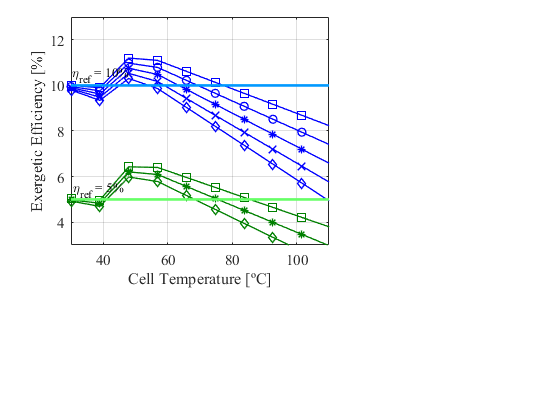


eqn(8) = beta == 0.005;
eqn(9) = T_fria==30;
eqn(10) = T_gelada==5;
eqn(11) = COP_chiller==0.55;
eqn(12) = T_amb==28;
eqn(13) = Irrad==G;
eqn(14) = FR_Tau_a==0.574/(1-0.123);
eqn(15) = FR_UL==4.85;
eqn(16) = eta_ref==0.2;
eqn(17) = COP_e == 3;
clear y x

for k = 1:5
 bet(k) = 0.001+(k-1)/4*0.004;
 eqn(8) = beta == bet(k);
 for j=1:2
  switch concentration
    case 'yes'
        eta_r(j) = 0.1+(j-1)/1*0.1;
    otherwise
        eta_r(j) = 0.05+(j-1)/1*0.05;
    end
  eqn(16) = eta_ref==eta_r(j);
  for i=1:20
    x(i) = 30+(i-1)/19*170; % 90
    if x(i) < 40
        eqn(11) = COP_chiller==0.01;
    elseif x(i) < 50
        eqn(11) = COP_chiller==0.55*(x(i)-40)/10;
    else
        eqn(11) = COP_chiller==0.55;
    end
    eqn(7) = T_cel==x(i);
    S=vpasolve(eqn);
    if max(S.eta_2)>0 & isreal(max(S.eta_2))
        switch opt
            case 'heat'
                y(i,2*(k-1)+j)=max(S.eta_2);
            otherwise
                y(i,2*(k-1)+j)=max(S.eta_2chiller);
        end
    else
        y(i,2*(k-1)+j) = 0;
    end
  end
 end
end
y = double(y);
xx = 30:10:200; %130;
yy = zeros(size(xx,2),size(y,2));
for i = 1:size(y,2)
     y1 = y(:,i);
     pp = csaps(x,y1);
     yy(:,i) = fnval(pp,xx)';
end
yy(:,size(yy,2)+1) = eta_r(1);
yy(:,size(yy,2)+1) = eta_r(2);
y(:,size(y,2)+1) = eta_r(1);
y(:,size(y,2)+1) = eta_r(2);

switch concentration
    case 'yes'
        Exergia_Com_graf(xx,yy*100,opt)
    otherwise
        Exergia_Sem_graf(x,y*100,opt)
end